load ("Sensor_Data.mat")

Pay atention to laser time sample T_laser= 0.4 s

Laser_dist=polar_laser_data(1,2:683)% First and last column are time

Laser_dist =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   886   880   864   864   864   876   889   904   904   905   908   905   904   901   900   900   896   896   892   889   885   885   883   883   883   883


ang_laser=linspace(-120*pi/180,120*pi/180,682)

ang_laser =    -2.0944   -2.0882   -2.0821   -2.0759   -2.0698   -2.0636   -2.0575   -2.0513   -2.0452   -2.0390   -2.0329   -2.0267   -2.0206   -2.0144   -2.0083   -2.0021   -1.9960   -1.9898   -1.9837   -1.9775   -1.9714   -1.9652   -1.9591   -1.9529   -1.9468   -1.9406   -1.9345   -1.9283   -1.9222   -1.9160   -1.9099   -1.9037   -1.8976   -1.8914   -1.8853   -1.8791   -1.8730   -1.8668   -1.8607   -1.8545   -1.8484   -1.8422   -1.8361   -1.8299   -1.8238   -1.8176   -1.8115   -1.8053   -1.7991   -1.7930


x_l=cos(ang_laser).*Laser_dist

x_l = 1.0e+03 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -0.3253   -0.3181   -0.3073   -0.3024   -0.2974   -0.2964   -0.2957   -0.2954   -0.2902   -0.2852   -0.2809   -0.2746   -0.2690   -0.2628   -0.2572   -0.2519   -0.2455   -0.2402   -0.2338   -0.2278   -0.2215   -0.2162   -0.2105   -0.2052   -0.1999   -0.1946


y_l=sin(ang_laser).*Laser_dist

y_l = 1.0e+03 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -0.8241   -0.8205   -0.8075   -0.8094   -0.8112   -0.8243   -0.8384   -0.8544   -0.8562   -0.8589   -0.8635   -0.8623   -0.8630   -0.8618   -0.8625   -0.8640   -0.8617   -0.8632   -0.8608   -0.8593   -0.8568   -0.8582   -0.8576   -0.8588   -0.8601   -0.8613


Robot_pose=transl(0,0,0)*trotz(-pi/2)

Robot_pose =      0     1     0     0
    -1     0     0     0
     0     0     1     0
     0     0     0     1


Laser_mapped=Robot_pose*[x_l;y_l;zeros(1,682);ones(1,682)]

Laser_mapped = 1.0e+03 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -0.8241   -0.8205   -0.8075   -0.8094   -0.8112   -0.8243   -0.8384   -0.8544   -0.8562   -0.8589   -0.8635   -0.8623   -0.8630   -0.8618   -0.8625   -0.8640   -0.8617   -0.8632   -0.8608   -0.8593   -0.8568   -0.8582   -0.8576   -0.8588   -0.8601   -0.8613
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.3253    0.3181    0.3073    0.3024    0.2974    0.2964    0.2957    0.2954    0.2902    0.2852    0.2809    0.2746    0.2690    0.2628    0.2572    0.2519    0.2455    0.2402    0.2338    0.2278    0.2215    0.2162    0.2105   

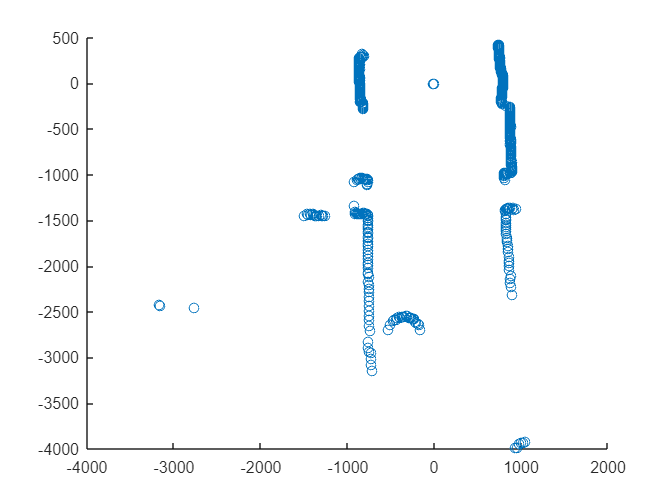

scatter(Laser_mapped(1,:),Laser_mapped(2,:))

r=0.1

r = 0.1000

N=10

N = 10